clear
clc
close all

#### Reading the audio file

[signal,Fs] = audioread('listen-to-the-ancient-egyptions-tv .wav');

# `Psychoacoustic Model `

# `Computing SPL`

### Signal Spectrum after FFT

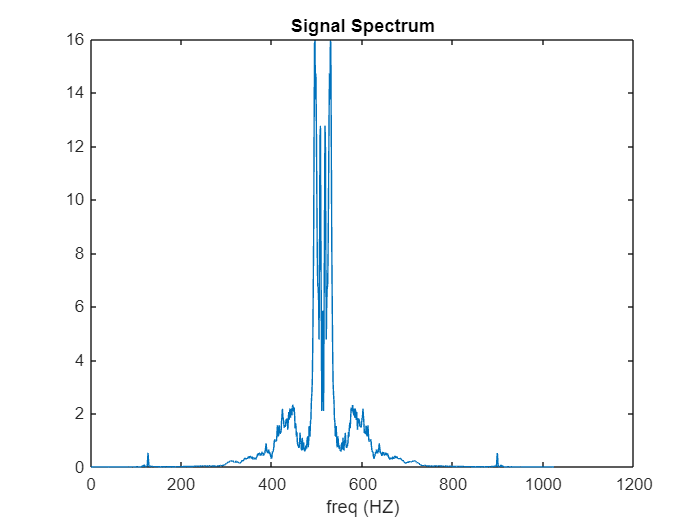

X = load('Signal_Spectrum.mat');
Signal_Spectrum = (X.Signal_Spectrum);
n = 0:length(Signal_Spectrum)-1;
plot(n,Signal_Spectrum)
xlabel('freq (HZ)')
title('Signal Spectrum')

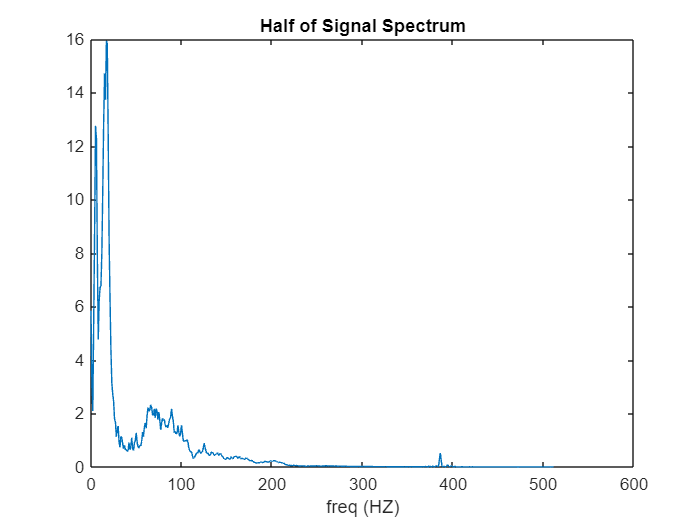

half_spectrum = X.Signal_Spectrum(513:end);
n = 0:length(half_spectrum)-1;

plot(n,half_spectrum)
xlabel('freq (HZ)')
title('Half of Signal Spectrum')

N = 1024;
f_vector = linspace(-Fs/2,Fs/2,N);
half_freq = f_vector(N/2+1:end);

### SPLs computing and evaluating

Lk = Lk_fn(N,half_spectrum)

Lk =    61.4100   56.0346   52.4889   60.8505   65.0221   68.1871   67.8572   64.0279   59.6446   61.9208   62.5920   62.7029   64.1634   66.3708   68.2824   69.4292   68.8269   70.1209   70.0547   67.9199   64.6587   62.0976   58.9225   56.0485   54.7868   53.8726   51.1547   50.5573   47.1825   48.9046   49.7552   45.6072   43.4762   47.1908   46.9903   44.7957   42.7806   44.2815   42.3369   42.1767   41.4054   41.8385   45.2982   42.2413   44.0697   46.8267   42.5260   41.9356   45.3011   46.0320


q_threshold = threshold_in_quiet(half_freq)

q_threshold =   127.5332   52.9506   35.1831   26.8762   21.9777   18.7146   16.3701   14.5959   13.2017   12.0742   11.1414   10.3555    9.6833    9.1008    8.5907    8.1397    7.7376    7.3766    7.0503    6.7537    6.4826    6.2337    6.0040    5.7913    5.5936    5.4090    5.2363    5.0740    4.9211    4.7767    4.6398    4.5097    4.3858    4.2675    4.1542    4.0455    3.9408    3.8400    3.7424    3.6479    3.5562    3.4669    3.3798    3.2947    3.2113    3.1294    3.0489    2.9695    2.8911    2.8136


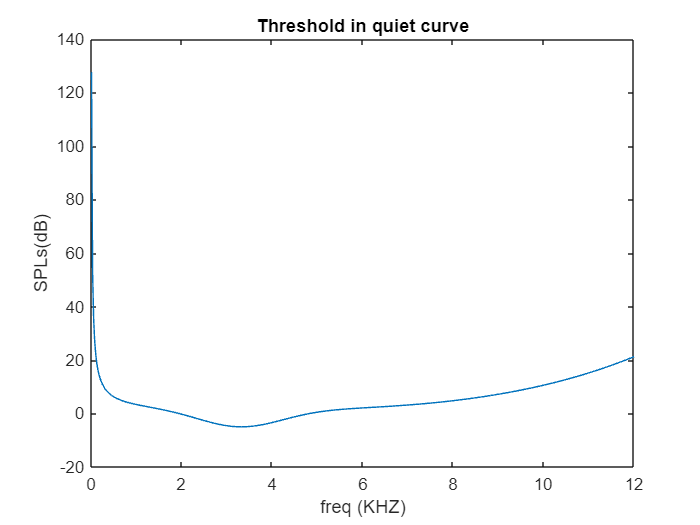


plot(half_freq/1000,q_threshold);
title('Threshold in quiet curve')
xlabel('freq (KHZ)')
ylabel('SPLs(dB)')

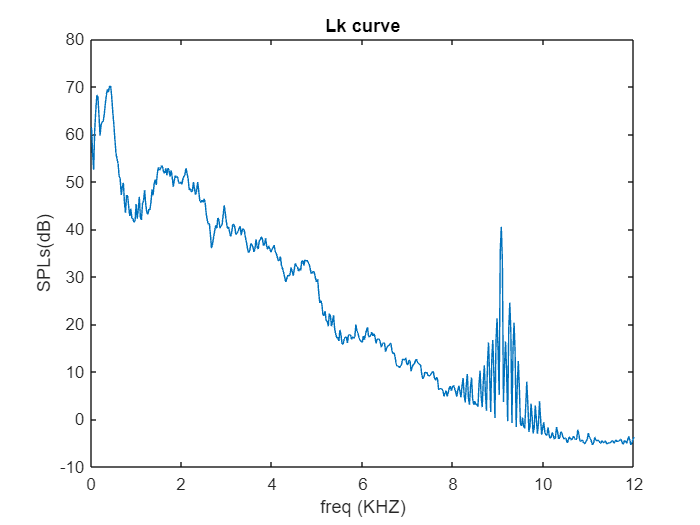

plot(half_freq/1000,Lk);
title('Lk curve')
xlabel('freq (KHZ)')
ylabel('SPLs(dB)')

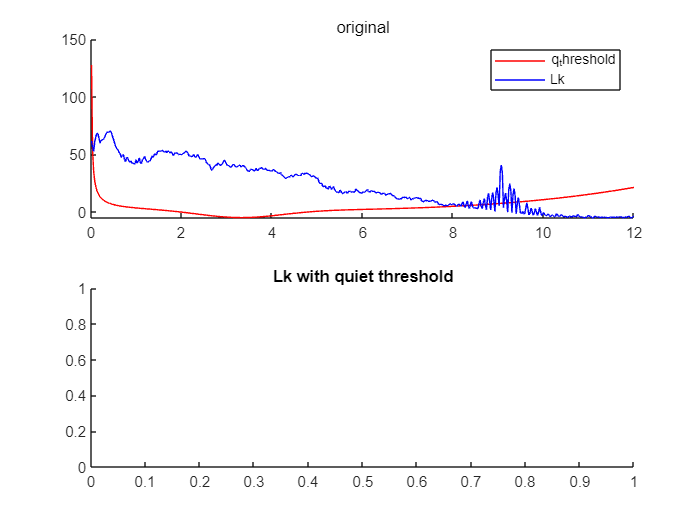


subplot(2,1,2);
title('Lk with quiet threshold');

subplot(2,1,1);

subtitle('original')
hold on
plot(half_freq/1000,q_threshold,Color='r');
plot(half_freq/1000,Lk,Color='b');
legend({'q_threshold','Lk'})
hold off

% set zeros to Lks that is less than the quite threshold
indices = q_threshold>Lk;
Lk(indices) = 0;

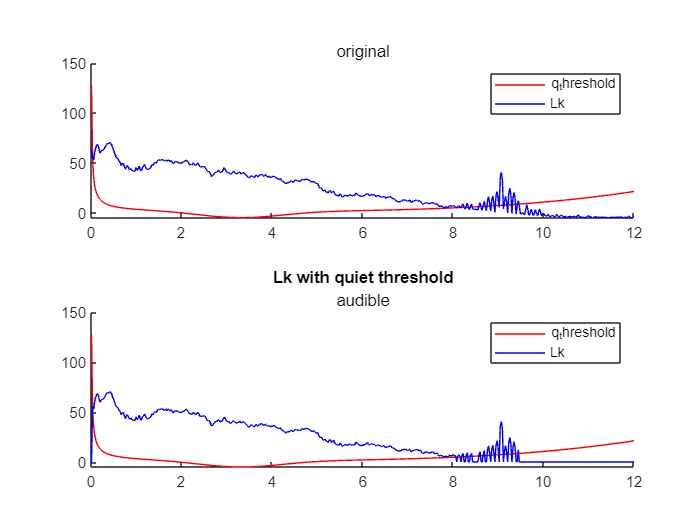

subplot(2,1,2);
subtitle('audible')
hold on
plot(half_freq/1000,q_threshold,Color='r');
plot(half_freq/1000,Lk,Color='b');
legend({'q_threshold','Lk'})
hold off

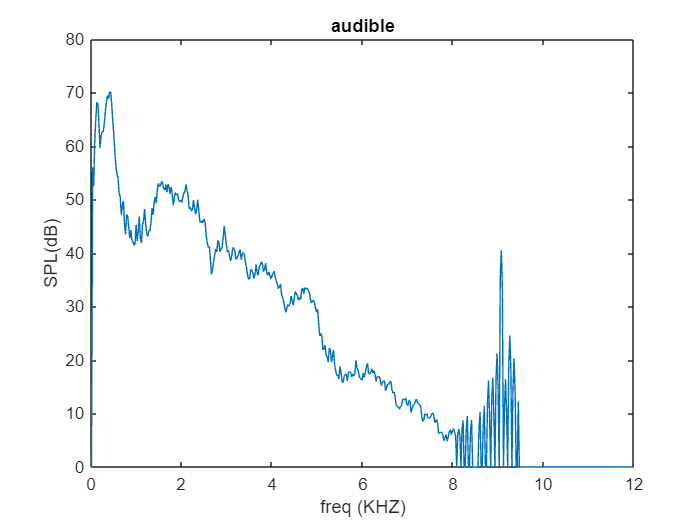

close all
plot(half_freq/1000,Lk);
title('audible')
xlabel('freq (KHZ)')
ylabel('SPL(dB)')

# `Psychoacoustic Model `

# Separation of Tonal & Non-Tonal Components

sub_num = 32;
sub_band_Matrix = divide2sub_bands(Lk,sub_num);
size(sub_band_Matrix)

ans =     32    16


f = 0:15;

for i = 1 : sub_num
    figure(i)
    f = f + 16*(i-1);
    sub = sub_band_Matrix(i,:);
    % stem(f,sub);
    % Find the peaks in the vector
%     if i == 10 || i == 27
%         disp('error here');
%     end
    [peakValues, peakIndices] = Find_maximas(sub);
%     peakIndices-1 + 16*(i-1)
%     peakValues
    % initialize maskees vector 
    maskees = zeros(1,length(peakValues));
    for j = 1: length(peakValues)
        index = peakIndices(j)+16*(i-1);
        % peakValues(j) is the max spl of that sub band 
        % half_freq(index) is the real value of the freq
        maskees(j) = masking_threshold(peakValues(j),half_freq(index));
        if peakValues(j) ~= 0

            f2_spl = threshold_in_quiet(maskees(j));
            y = [peakValues(j) f2_spl];
            x = [half_freq(index) maskees(j)];
            p = spreading_fn(x,y);        
%             x1 = linspace(half_freq(index),maskees(j));
%             y1 = polyval(p,x1);
%             plot(x1,y1);
            for xx = index+1 : 16*i
                if half_freq(xx+1) < maskees(j)
                    llk = Lk(xx);
                    pp = polyval(p,half_freq(xx+1));
                    if llk < pp
                        Lk(xx)=0;
                    end
                end
            end
            
        end
    end
end
Lk

Lk =          0   56.0346         0         0         0         0         0         0         0         0         0         0         0         0         0         0   68.8269   70.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0   43.4762   47.1908         0         0         0         0         0         0         0         0         0         0         0         0         0         0   45.3011   46.0320


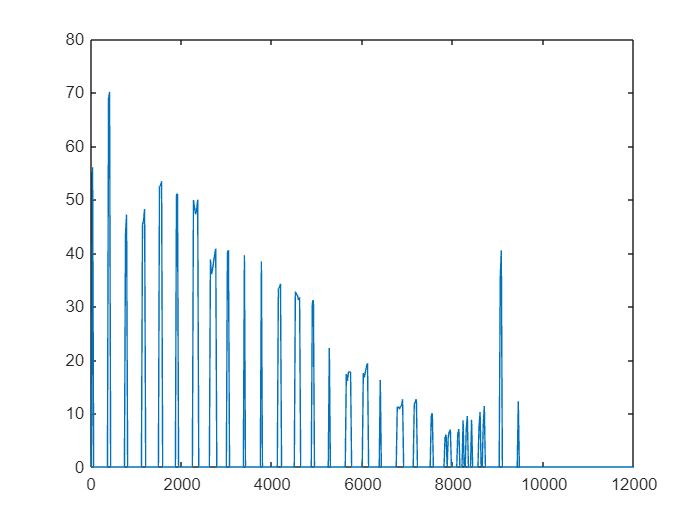

plot(half_freq,Lk)